clc
% clear all

Leyendo la base de datos, se ve que contiene 252 filas y 753 columnas, las filas corresponden a todos los sujetos, y las colunmas a las variables medidas sobre las señales de voz

data = readtable("pd_speech.csv");
summary(data);

Variables:

    rownames: 252×1 double

        Values:

            Min            1  
            Median     126.5  
            Max          252  

    gender: 252×1 double

        Values:

            Min          0    
            Median       1    
            Max          1    

    PPE: 252×1 double

        Values:

            Min       0.31435 
            Median    0.80204 
            Max       0.86993 

    DFA: 252×1 double

        Values:

            Min       0.55597 
            Median    0.69941 
            Max       0.85111 

    RPDE: 252×1 double

        Values:

            Min       0.19385 
            Median    0.48312 
            Max       0.82648 

    meanPeriodPulses: 252×1 double

        Values:

            Min       0.0032726
            Median    0.0060918
            Max        0.011608

    stdDevPeriodPulses: 252×1 double

  

Conteo de hombres y mujeres por cada grupo de Parkinson y Control:

data_gender=groupsummary(data,["gender","class"])

data_gender = 4×3 table
    gender       class       GroupCount
    ______    ___________    __________

      0       {'PD'     }        81    
      0       {'control'}        41    
      1       {'PD'     }       107    
      1       {'control'}        23    


Selección de las variables de interés. Esta es la tabla de datos que usarán para desarrollar el proyecto:

x=data(:,["gender" "class" "PPE" "DFA" "RPDE"])

x = 252×5 table
    gender       class         PPE        DFA       RPDE  
    ______    ___________    _______    _______    _______

      1       {'PD'     }    0.82339    0.69637    0.56725
      0       {'PD'     }    0.41564    0.79399    0.59245
      1       {'PD'     }    0.80197    0.61997    0.52056
      0       {'PD'     }    0.82871     0.6261    0.53718
      0       {'PD'     }    0.83129     0.7794    0.72672
      1       {'PD'     }    0.82252    0.62208    0.35766
      1       {'PD'     }    0.80003    0.66728    0.39158
      1       {'PD'     }    0.52919    0.77486    0.71268
      1       {'PD'     }    0.81879     0.6424    0.50103
      1       {'PD'     }     0.8462    0.60863    0.43147
      1       {'PD'     }    0.48983    0.65193      0.638
      1       {'control'}    0.82284    0.6641

Con la tarea de "Compute by Group" se pueden obtener tablas de datos estadísticos (Computations stats) de varias variables (compute on), incluso agrupadas según género y clase (Group by).

**1) Utilice la tarea en tiempo real de Matlab “compute by group” para calcular múltiples  estadísticas descriptivas de la PPE, DFA y RPDE (media, max, min, std, var, datos  perdidos, etc) por cada grupo de datos: control_hombre, control_mujer, EP_hombre,  EP_mujer**

% Compute group summary
BD = groupsummary(x,["gender","class"],["mean","median","mode","max", ...
    "min","std","var","nummissing"],vartype("numeric"));
BD.GroupCount = []

BD = 4×34 table
    gender       class       mean_gender    median_gender    mode_gender    max_gender    min_gender    std_gender    var_gender    nummissing_gender    mean_PPE    median_PPE    mode_PPE    max_PPE    min_PPE    std_PPE      var_PPE     nummissing_PPE    mean_DFA    median_DFA    mode_DFA    max_DFA    min_DFA    std_DFA      var_DFA     nummissing_DFA    mean_RPDE    median_RPDE    mode_RPDE    max_RPDE    min_RPDE    std_RPDE    

**2) Realice un análisis exploratorio de los datos dividiendo los datos según los grupos control y EP, y subdividiendo según el género así:**

**a. Realice gráficos de barras para mostrar la distribución de los datos (control y EP) vs género**

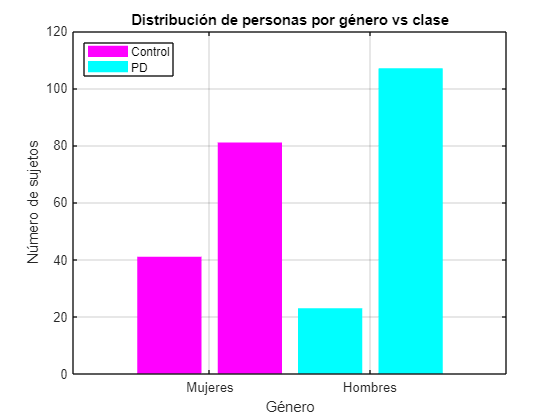

% Filtrar los datos por clase y género
controlFemenino = data_gender{(data_gender.gender == 0) & (data_gender.class == "control"), 'GroupCount'};
PDfemenino = data_gender{(data_gender.gender == 0) & (data_gender.class == "PD"), 'GroupCount'};
controlMasculino = data_gender{(data_gender.gender == 1) & (data_gender.class == "control"), 'GroupCount'};
PDmasculino = data_gender{(data_gender.gender == 1) & (data_gender.class == "PD"), 'GroupCount'};

% Gráfico de barras
bar([1, 2], [controlFemenino, PDfemenino], 'FaceColor', 'magenta', 'EdgeColor', 'none'); % Mujeres en rosado
hold on;
bar([3, 4], [controlMasculino, PDmasculino], 'FaceColor', 'cyan', 'EdgeColor', 'none'); % Hombres en cyan
hold off;

xticks([1.5 3.5]);
xticklabels({'Mujeres', 'Hombres'});
xlabel('Género');
ylabel('Número de sujetos');
title('Distribución de personas por género vs clase');

legend({'Control', 'PD'}, 'Location', 'northwest');

grid on;

b. Realice los histogramas de PPE, DFA, RPDE por grupos de muestras. Además, obtenga y grafique la PDF.

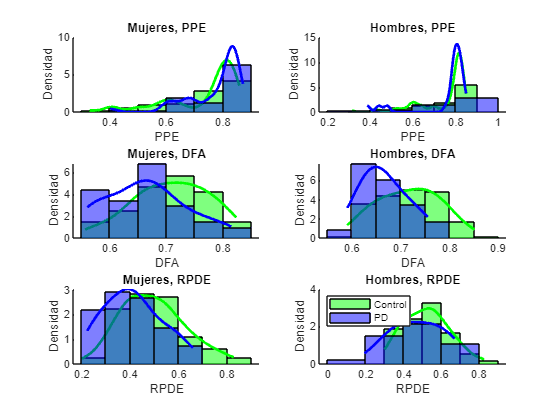

variables = {'PPE', 'DFA', 'RPDE'};
generos = unique(data.gender);
clases = unique(data.class);
groupLabels = {'Mujer, PD', 'Mujer, control', 'Hombre, PD', 'Hombre, control'};

figure;
for v = 1:length(variables)
    varName = variables{v};
    for g = 1:length(generos)
        subplot(length(variables), length(generos), (v-1)*length(generos)+g);
        hold on;
        
        % Green: contro, Blue: PD
        colors = {'green', 'blue'};
        
        h = zeros(1, length(clases));
        
        for c = 1:length(clases)
            % Filtrar datos por género y clase
            filteredData = data(data.gender == generos(g) & strcmp(data.class, clases(c)), :);
            
            % Histograma
            h(c) = histogram(filteredData.(varName), 'Normalization', 'pdf', 'FaceColor', colors{c}, 'FaceAlpha', 0.5);
            
            % PDF
            pd = fitdist(filteredData.(varName),'Kernel','Kernel','normal');
            x_values = linspace(min(filteredData.(varName)), max(filteredData.(varName)), 100);
            y_values = pdf(pd, x_values);
            plot(x_values, y_values, 'LineWidth', 2, 'Color', colors{c});
        end
        
        % Título
        genderStr = 'Mujeres';
        if generos(g) == 1
            genderStr = 'Hombres';
        end

        title([genderStr ', ' varName]);
        xlabel(varName);
        ylabel('Densidad');
        hold off;
    end
end

legend(h, {'Control', 'PD'}, 'Location', 'northwest');

c. Obtenga los boxplot de las variables PPE, DFA y RPDE para las cuatro muestras.

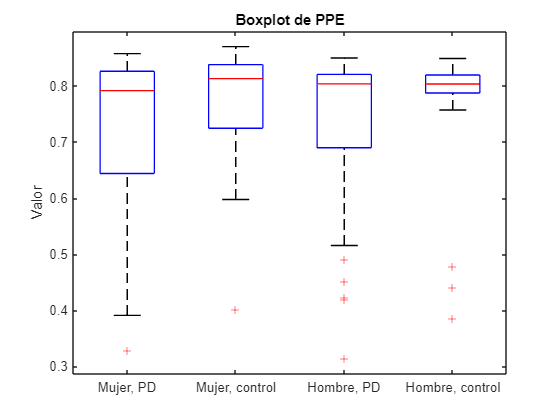

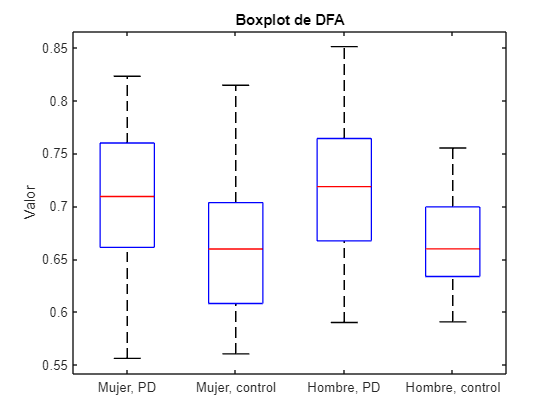

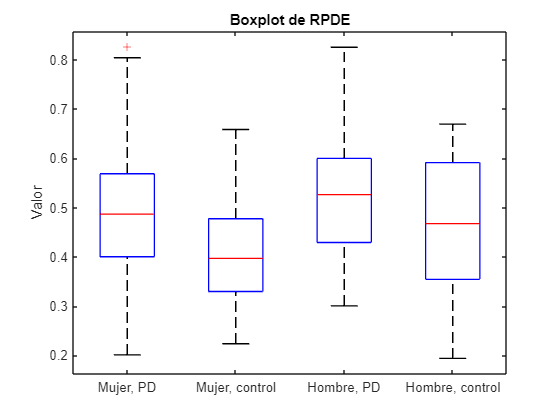

variables = {'PPE', 'DFA', 'RPDE'};
generos = [0, 0, 1, 1]; % Sin esto no funciona
clases = {'PD', 'control', 'PD', 'control'}; % Sin esto tampoco
groupLabels = {'Mujer, PD', 'Mujer, control', 'Hombre, PD', 'Hombre, control'};

for v = 1:length(variables)
    varName = variables{v};
    figure;
    boxData = [];
    groupVector = [];
    
    % Filtrado de datos
    for i = 1:length(groupLabels)
        % Hace un arreglo que coincidan con generos(i) y clases(i)
        filteredData = data(data.gender == generos(i) & strcmp(data.class, clases(i)), :);
        boxData = [boxData; filteredData.(varName)];
        % Crea un vector del mismo tamaño de filteredData.(varName), lleno de i
        groupVector = [groupVector; i*ones(size(filteredData.(varName)))];
    end
    
    % Boxplot
    boxplot(boxData, groupVector, 'Labels', groupLabels);
    title(['Boxplot de ' varName]);
    ylabel('Valor');
end

## Análisis inferencial

- Compare la Puntuación en la disfonía (PPE), de los diferentes grupos de sujetos (EP y control) y determine si existen diferencias significativas.

- Determine si la capacidad de las cuerdas vocales (RPDE) de los sujetos con EP es menor, mayor o no difiere significativamente respecto al de los sujetos control. Discuta los resultados encontrados y compare con la literatura.

**3. Tome solo el conjunto de datos del grupo de pacientes con Parkinson y determine si la autosimilitud estocástica del ruido (DFA) es mayor en los hombres que en las mujeres. Discuta sus resultados y compare con la literatura.**

Primero vamos a conocer la distribución de los datos.

Primero determinemos la hipotesis nula y alternativa:

- h0: Los datos *PPE, DFA *y* RPDE *siguen una distribución normal.

- h1: Los datos *PPE, DFA *y* RPDE* **no** siguen una distribución normal.

Como tenemos una base de datos mayor a 50 observaciones procederemos a realizar una prueba de **Kolmogorov-Smirnov** para las variables mean_PPE, mean_DFA y mean_RPDE. Esta prueba determinará si la hipotesis nula se rechaza o no se rechaza. La prueba de **Kolmogorov-Smirnov **nos mostrará diferentes valores p, utilizando un nivel de significancia de 0.05, si un valor p es menor a dicho nivel; será fuerte evidencia para rechazar la hipotesis nula.

% Se hará la prueba a todos los grupos
grupos = {'PD', 'control'};

generos = {'Mujer', 'Hombre'}; % 'Mujer' para 0, 'Hombre' para 1

% Se guardarán los datos en una tabla
resultados = table();

for i = 1:length(grupos)
    for j = 1:length(generos)
        % Extraer los datos del grupo y género actual
        grupo = data(data.gender == (j-1) & strcmp(data.class, grupos{i}), :);

        % Kolmogorov-Smirnov para PPE
        [h_PPE, p_PPE] = kstest(grupo.PPE);

        % Kolmogorov-Smirnov para DFA
        [h_DFA, p_DFA] = kstest(grupo.DFA);

        % Kolmogorov-Smirnov para RPDE
        [h_RPDE, p_RPDE] = kstest(grupo.RPDE);

        % Almacenar los resultados en la tabla
        resultados = [resultados; table({grupos{i}}, {generos{j}}, h_PPE, p_PPE, h_DFA, p_DFA, h_RPDE, p_RPDE)];
    end
end

resultados.Properties.VariableNames = {'Grupo', 'Genero', 'H_PPE', 'p_PPE', 'H_DFA', 'p_DFA', 'H_RPDE', 'p_RPDE'};

disp(resultados);

       Grupo         Genero      H_PPE      p_PPE       H_DFA      p_DFA       H_RPDE      p_RPDE  
    ___________    __________    _____    __________    _____    __________    ______    __________

    {'PD'     }    {'Mujer' }    true      5.291e-30    true     6.0551e-37    true      5.1501e-26
    {'PD'     }    {'Hombre'}    true      6.201e-41    true      5.028e-50    true      9.8345e-37
    {'control'}    {'Mujer' }    true     1.1818e-18    true     2.8312e-19    true      2.7443e-13
    {'control'}    {'Hombre'}    true     2.0395e-09    true     1.5506e-11    true      1.2335e-07



Fijemonos exclusivamente en los grupos de personas con Enfermedad de Parkinson y en la variable DFA. Podemos observar que el** valor p es de 6.0551e-37 en mujeres y 5.028e-50 en hombres**, eso indica que la hipotesis nula se rechaza, dando como conclusión que:

- Para todos los grupos y géneros **(en este caso nos importa DFA en pacientes con PD)**, el valor de H es ‘true’, lo que significa que la hipótesis nula fue rechazada. En este caso, la hipótesis nula era que los datos siguen una distribución normal. Por lo tanto, rechazar la hipótesis nula significa que** los datos no siguen una distribución normal**.

Para comparar si la autosimilitud estocástica del ruido (DFA) es mayor en los hombres que en las mujeres en el grupo de pacientes con Parkinson, se utilizará una prueba que compare las medianas de dos grupos independientes, ya que los datos no siguen una distribución normal.

La prueba **U de Mann-Whitney** es la más adecuada para este caso. Esta prueba se utiliza para determinar si hay una diferencia significativa entre las medianas de dos grupos independientes. En este caso, los dos grupos son los hombres y las mujeres dentro del grupo de pacientes con Parkinson.

Primero determinemos las hipotesis nula y alternativa:

- h0: la autosimilitud estocástica del ruido (DFA) es igual o menor en hombres que en mujeres con enfermedad de parkison.


$$\mu_{\textrm{hombres}} \le \;\mu_{\textrm{mujeres}}$$


- h1: la autosimilitud estocástica del ruido (DFA) en hombres con parkinson es mayor que en mujeres con parkinson.


$$\mu_{\textrm{hombres}} >\mu_{\textrm{mujeres}}$$


Ahora procedemos a realizar la prueba.

% Datos DFA de hombres y mujeres con Parkinson
DFA_hombres = data.DFA(data.gender == 1 & strcmp(data.class, 'PD'));
DFA_mujeres = data.DFA(data.gender == 0 & strcmp(data.class, 'PD'));

% Prueba U de Mann-Whitney
[p, h] = ranksum(DFA_hombres, DFA_mujeres, 'tail', 'right');

fprintf('Resultado de la prueba U de Mann-Whitney:\nH = %d, p = %.5f\n', h, p);

Resultado de la prueba U de Mann-Whitney:
H = 0, p = 0.27758


El valor de H es 0, lo que significa que **no se puede rechazar la hipótesis nula**. El valor p es 0.27758, que es mayor que el nivel de significancia de 0.05. Esto significa que no hay suficiente evidencia para rechazar la hipótesis nula a favor de la hipótesis alternativa.

Por lo tanto, la conclusión es que no hay suficiente evidencia para afirmar que la autosimilitud estocástica del ruido (DFA) en hombres con Parkinson es mayor que en las mujeres. Incluso aumentando el nivel de significancia a 0.10, se sigue sin tener evidencia suficiente para rechazar la hipotesis nula.

Estos resultados parecen estar en línea con la literatura existente. Por ejemplo, un estudio publicado en *Nature* sugiere que las diferencias de género en la enfermedad de Parkinson pueden no ser tan pronunciadas como se pensaba anteriormente. Igualmente se continua la discusión, pues otro estudio publicado en el *Journal of Neural Transmission* informa sobre la presencia de un patrón relacionado con el género en la frecuencia de los síntomas no motores y las fluctuaciones no motoras en los pacientes con Parkinson.

Es importante tener en cuenta que aunque estos estudios proporcionan información valiosa sobre las diferencias de género en la enfermedad de Parkinson, no abordan específicamente las diferencias en la DFA. Por lo tanto, aunque los resultados están en línea con la literatura existente en términos generales, no son fuertemente concluyentes respecto a la variable DFA.

Referencias:

- [Gender gap in deep brain stimulation for Parkinson’s disease (nature.com)](https://www.nature.com/articles/s41531-022-00305-y.pdf)

- [Gender differences in non-motor fluctuations in Parkinson’s disease | Journal of Neural Transmission (springer.com)](https://link.springer.com/article/10.1007/s00702-023-02679-6)

**4. Se desea probar si la variable independiente género, tienen un efecto sobre la Disfonía (PPE). Discuta los resultados obtenidos.**

Un modelo de regresión es una buena opción para probar si la variable independiente (género) tiene un efecto sobre la Disfonía (PPE). En este caso, como la variable PPE es continua, el modelo que se utilizará será uno de regresión lineal.

% Extraer los datos de PPE y género
PPE = data.PPE;
genero = data.gender;

% Modelo de regresión lineal
mdl = fitlm(genero, PPE);

disp(mdl);

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE       tStat       pValue   
                   _________    ________    ______    ___________

    (Intercept)      0.74451    0.010884    68.401    7.3316e-164
    x1             0.0034446    0.015154    0.2273        0.82037


Number of observations: 252, Error degrees of freedom: 250
Root Mean Squared Error: 0.12
R-squared: 0.000207,  Adjusted R-Squared: -0.00379
F-statistic vs. constant model: 0.0517, p-value = 0.82


En el modelo de regresión lineal, la variable dependiente (la que se está tratando de predecir) es la Disfonía (PPE), y la variable independiente (la que se está usando para hacer la predicción) es el género. Con lo anterior en mente se puede concluir lo siguiente:

- **Coeficiente para el género**: El género está codificado como 0 para mujeres y 1 para hombres. Por lo tanto, el coeficiente para el género representa el cambio promedio en la Disfonía (PPE) cuando el género cambia de 0 (mujeres) a 1 (hombres). Dado que el coeficiente es positivo (0.0034446), esto indica que, en promedio, la Disfonía (PPE) es 0.0034446 unidades mayor en hombres que en mujeres, manteniendo todo lo demás constante.

- **Intercepto del modelo**: El intercepto del modelo representa el valor promedio de la Disfonía (PPE) cuando todas las variables independientes son 0. En el modelo, esto correspondería al caso en que el género es 0, es decir, para las mujeres. Por lo tanto, el intercepto representa la Disfonía (PPE) promedio para las mujeres, manteniendo todo lo demás constante.

Ahora respecto a la precisión en la predicción

- **R-cuadrado**: El valor de R-cuadrado es muy pequeño (0.000207), lo que indica que el modelo explica muy poca de la variabilidad en la Disfonía (PPE). Esto sugiere que hay otras variables, no incluidas en el modelo, que podrían ser importantes para predecir la Disfonía (PPE).

Según este modelo de regresión lineal, no hay suficiente evidencia para concluir que el género tiene un efecto significativo en la Disfonía (PPE) en pacientes con Parkinson.